dr = 1;
R_a = 47;
R_b = 1:dr:2*10^6;
uC = [1 2.2 3.3 4.7 10] .* 10^-6;
nC = [1 2.2 4.7 10 22 47 100 220 470] .* 10^-9;
pC = [1 2.2 4.7 10 22 47 100 220 470] .* 10^-12;
test_C = [1 4.7 10 47 100 220 470 1000] .* 10^-9;
R_E12 = [1 1.2 1.5 1.8 2.2 3.3 3.9 4.7 5.6 6.8 8.2];
R_E6 = [1 2.2 3.3 4.7 6.8];
R_E3 = [1 2.2 4.7];


## Frequency

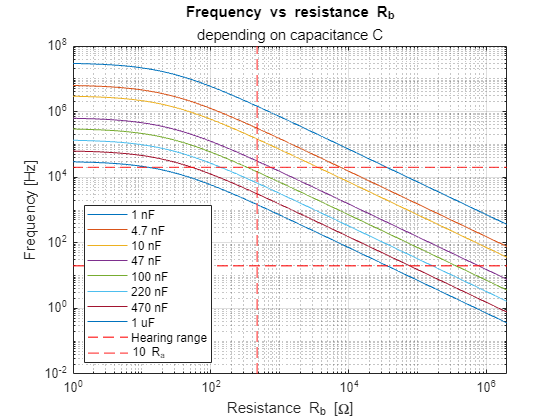

for c = test_C(1:size(test_C, 2))
    if c >= 10^-6
        c_legend = join([string(c * 10^6) "uF"]);
    elseif c >= 10^-9
        c_legend = join([string(c * 10^9) "nF"]);
    else
        c_legend = join([string(c * 10^12) "pF"]);
    end

    T = period(R_a, R_b, c);
    frequency = 1./T;
    % plot(R_b, frequency, "DisplayName", c_legend);
    loglog(R_b, frequency, "DisplayName", c_legend);
    % semilogx(R_b, frequency, "DisplayName", c_legend);
    % semilogy(R_b, frequency);
    legend("show");
    grid on;
hold on;
end
title("Frequency vs resistance R_b")
subtitle("depending on capacitance C")
xlabel("Resistance R_b [\Omega]")
ylabel("Frequency [Hz]")
yline(20000, "Color","red", "LineWidth", 1, "LineStyle","--", "DisplayName", "Hearing range");
yline(20, "Color","red", "LineWidth", 1, "LineStyle","--", "HandleVisibility","off");
xline(R_a .* 10,  "Color","red", "LineWidth", 1, "LineStyle","--", "DisplayName", "10 R_a");
legend("Location","southwest")
hold off;
print('../latex/img/fr_plot', '-depsc');

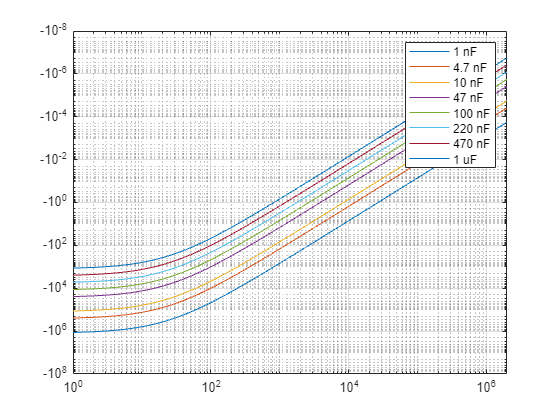

for c = test_C(1:size(test_C, 2))
    if c >= 10^-6
        c_legend = join([string(c * 10^6) "uF"]);
    elseif c >= 10^-9
        c_legend = join([string(c * 10^9) "nF"]);
    else
        c_legend = join([string(c * 10^12) "pF"]);
    end

    T = period(R_a, R_b, c);
    frequency = 1./T;
    loglog(diff(frequency), "DisplayName", c_legend);
    legend("show");
    grid on;
hold on;
end

## notes

A_4 = 440;
note_names = ["C", "C#", "D", "D#", "E", "F", "F#", "G", "G#", "A", "A#", "B"];
keyboard_notes = ["A", "A#", "B", "C", "C#", "D", "D#", "E", "F", "F#", "G", "G#", "A", "A#", "B", "C", "C#", "D", "D#", "E"];
c = 22 * 10^-9;
r_b = 1000:2*10^6;
r_a = 220;
notes = MIDInote(57:76);
% notes = MIDInote(17:76);
notes_resistance = inverse_period(notes, r_a, c);
T = period(r_a, r_b, c);
frequency = 1./T;
loglog(r_b, frequency, "DisplayName", "22 nF");
hold on;
loglog(notes_resistance, notes, ".", "DisplayName", "notes", MarkerSize=10);
legend("Location","southwest")
yline(20000, "Color","red", "LineWidth", 0.5, "LineStyle","--", "DisplayName", "Hearing range");

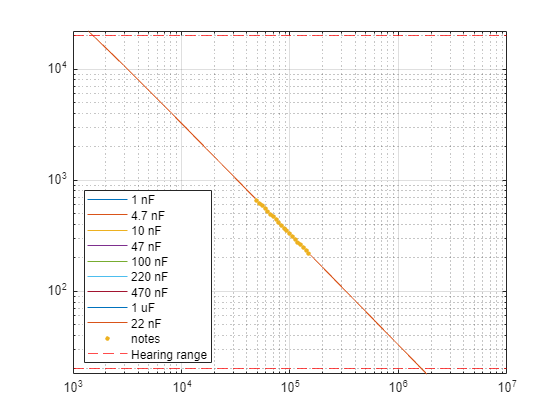

yline(20, "Color","red", "LineWidth", 0.5, "LineStyle","--", "HandleVisibility","off");
ylim([18 22000]);
grid on;
hold off;

## notes diffrence

notes_resistance_difference = 1:size(notes_resistance-1, 2);
notes_nearest_resistor = 1:size(notes_resistance-1, 2);
% notes_resistance_difference(1) = notes_resistance(1);
for r_multiplier = [1 10 100 1000 10000 100000 1000000]
    for k = 1:size(notes_resistance_difference, 2)
        if k >= 20
            break
        end
        notes_resistance_difference(k) = notes_resistance(k) - notes_resistance(k+1);
        temp = interp1(R_E12 .* r_multiplier, R_E12 .* r_multiplier, notes_resistance_difference(k), "nearest");
        if temp >= 0
            notes_nearest_resistor(k) = temp; 
        end
    end
end
bar_plot = [notes_resistance_difference; notes_nearest_resistor]

bar_plot = 1.0e+03 *

    8.3667    7.8971    7.4539    7.0355    6.6406    6.2679    5.9161    5.5841    5.2707    4.9749    4.6956    4.4321    4.1833    3.9485    3.7269    3.5178    3.3203    3.1340    2.9581    0.0200
    0.0010    8.2000    6.8000    6.8000    6.8000    6.8000    5.6000    5.6000    5.6000    4.7000    4.7000    4.7000    3.9000    3.9000    3.9000    3.3000    3.3000    3.3000    3.3000    0.0200


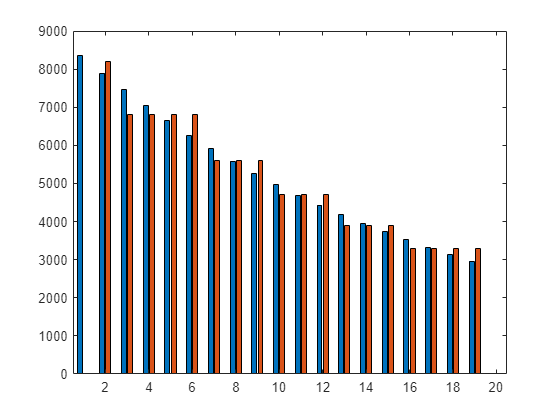

bar(bar_plot')

## testing

test_bar = [add_array(notes_resistance_difference); add_array(notes_nearest_resistor)]

test_bar = 1.0e+04 *

    0.8367    1.6264    2.3718    3.0753    3.7394    4.3662    4.9578    5.5162    6.0433    6.5407    7.0103    7.4535    7.8719    8.2667    8.6394    8.9912    9.3232    9.6366    9.9324    9.9344
    0.0001    0.8201    1.5001    2.1801    2.8601    3.5401    4.1001    4.6601    5.2201    5.6901    6.1601    6.6301    7.0201    7.4101    7.8001    8.1301    8.4601    8.7901    9.1201    9.1221


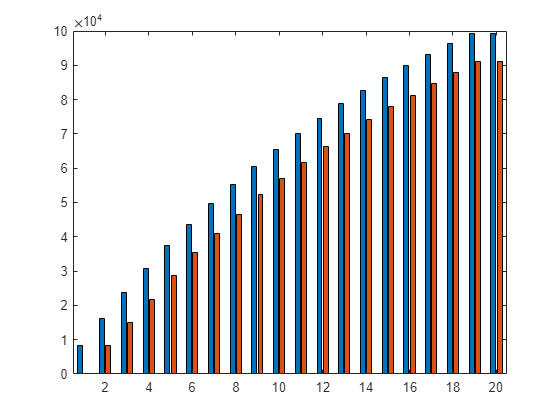

bar(test_bar');